# Quadratic programming and energy comsumption

## Initialisation

close all;
clc;
clear;

## Implementation

% fixed parameters
a = 0.9934;
bu = -2 * 1.0e-3;
be = 6.6 * 1.0e-3;
umin = 0;
umax = 100;

% other parameters
Np = 5;
nx = 1;
nu = 1;

To = 27; % ambient tempeture
Wo = 3;
W_K = Wo*ones(Np,1);
To_K = To*ones(Np,1);
F=zeros(Np,1);
Hu=zeros(Np,Np);
He = zeros(Np,Np);

for i=1:Np
    F(i)=a^i ; % F
    for j=1:i
        Hu(i,j)=a^(i-j)*bu; % Hu
        He(i,j) = a^(i-j)*be; % He
    end
end

W_K

W_K =      3
     3
     3
     3
     3


F

F =     0.9934
    0.9868
    0.9803
    0.9739
    0.9674


Hu

Hu =    -0.0020         0         0         0         0
   -0.0020   -0.0020         0         0         0
   -0.0020   -0.0020   -0.0020         0         0
   -0.0020   -0.0020   -0.0020   -0.0020         0
   -0.0019   -0.0020   -0.0020   -0.0020   -0.0020


He

He =     0.0066         0         0         0         0
    0.0066    0.0066         0         0         0
    0.0065    0.0066    0.0066         0         0
    0.0065    0.0065    0.0066    0.0066         0
    0.0064    0.0065    0.0065    0.0066    0.0066


## Feedback control

% Objective function
lambda=bu.^2; % to ensure the stability and convergence

Q=eye(nx);
R=lambda;

QT=zeros(nx*Np);
Ru=zeros(nu*Np);

for i =1:Np
    QT(nx*(i-1)+1:nx*i,nx*(i-1)+1:nx*i)=Q;
    Ru(nu*(i-1)+1:nu*i,nu*(i-1)+1:nu*i)=R;
end

## Optimal feedback (off-line computation)

First=zeros(nu,nu*Np);
First(nu,nu)=eye(nu);
K_Np=First*(Ru + Hu'*Hu)^(-1)*Hu'*F;

## Close-loop implementation

Hz = zeros((nx+nu)*Np);
Hz = blkdiag(Ru,QT);
Aeq = [-Hu eye(Np*nx)]; % Aeq*Z = beq
FirstZ = [First zeros(1,Np*nx)]; % Z = [U(K|k), T(K+1|k)]

Nsimu=30;
Tinit=2;
Tk=Tinit;
T = [];
for i=1:Nsimu
    T = [T Tk];
    beq = F*Tk + He*To_K - W_K;
    [Zopt,JNP] = quadprog(Hz,[],[],[],Aeq,beq);
    uk=FirstZ*Zopt; %optimal control U
    if uk > umax
        uk = umax;
    elseif uk < umin
        uk = umin;
    end
    uk
    Tkp1=a*Tk+bu*uk+be*To;
    Tk=Tkp1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 0


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 0


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 0


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 0


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 0


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 21.0955


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 57.0611


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 70.7598


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 75.9774


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 77.9647


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 78.7216


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.0099


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1197


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1615


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1774


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1835


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1858


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1867


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1870


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1872


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1872


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1872


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1872


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1872


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1872


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1872


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1873


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1873


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1873


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uk = 79.1873


T

T =     2.0000    2.1650    2.3289    2.4917    2.6535    2.8142    2.9316    2.9763    2.9934    2.9999    3.0023    3.0033    3.0036    3.0038    3.0038    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039    3.0039


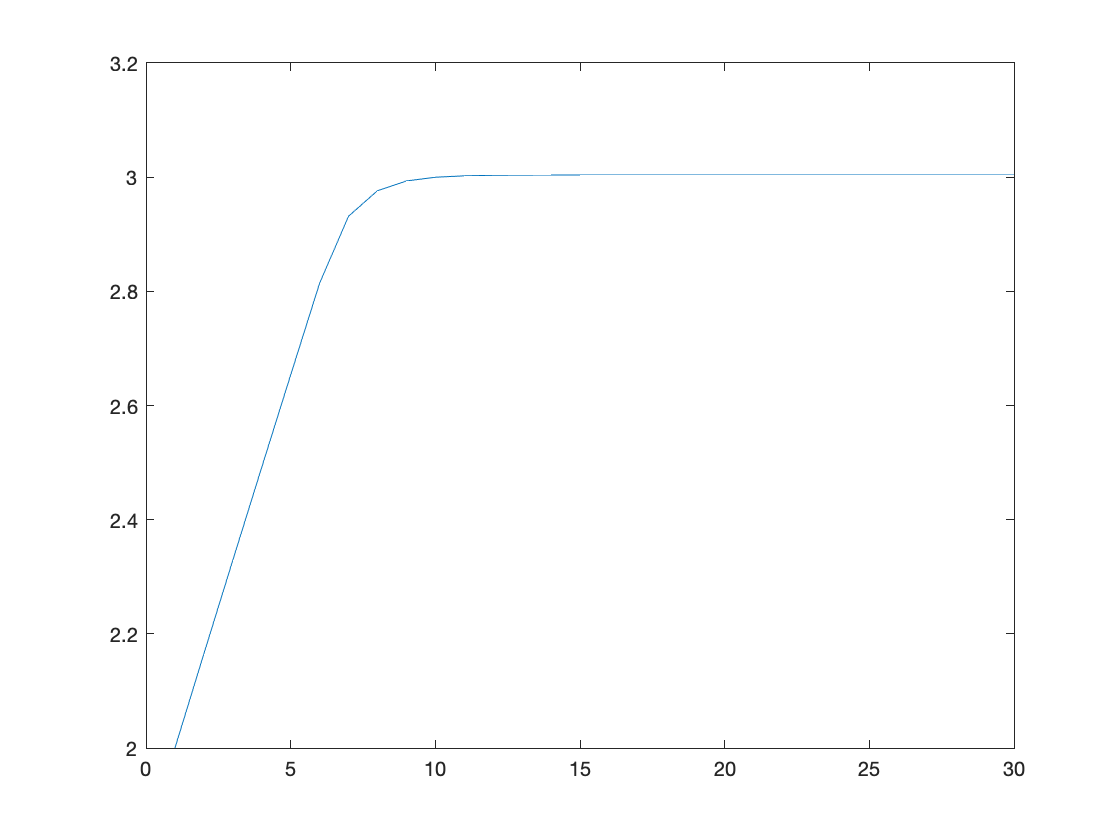

plot(1:Nsimu,T);

## Analysis of the closed-loop system

eigenvalues=eig(a-bu*K_Np)

eigenvalues = 0.3809

modeul = norm(eigenvalues(1),1)

modeul = 0.3809